# MVP CPR Frequency Analysis

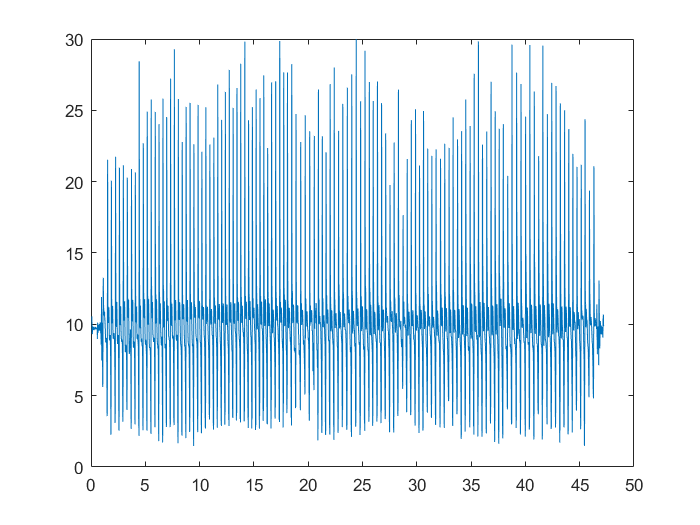

% import first and last column of xls data as double
% this is a data of me preforming CPR on my leg: )

accel = accel(2:end);
time = time(2:end);

% plot time domain data
figure(1)
plot(time,accel)

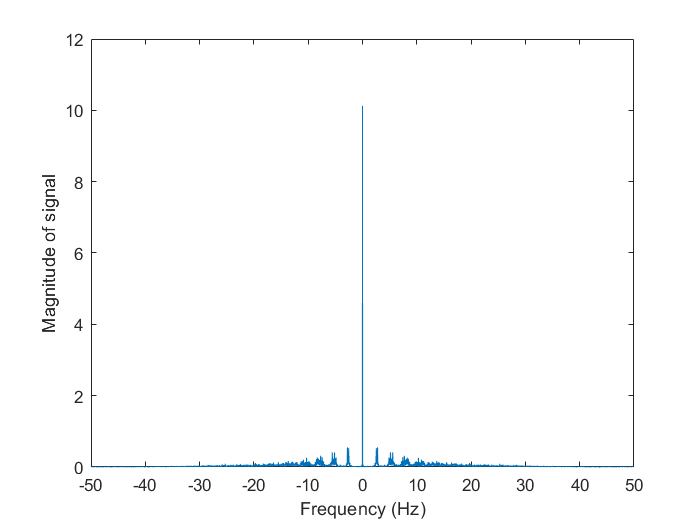

amp =    10.1238
    0.5486
    0.5486
    0.5281
    0.5281


freq = 2.7707



% total number of samples
N = length(time); 
% sampling rate: 
Fs = round(N/time(end)); % # of samples per time(sec)

% figure(2)
% for i=1:length(real_accel)
%     if real_accel(i)<10
%         real_accel(i) = 0;
%     end
% end

% perform DFT
% amp: max amplitude
% freq: dominant frequency (Hz)
[amp,freq] = make_freq_plot_max(accel,Fs)

freq_bpm = freq * 60; % convert from Hz to bpm

% calculate score
if freq_bpm <= 120 && freq_bpm >= 100
    score = 100;
    disp("Good job!")
elseif freq_bpm > 120
    score = 100 - (freq_bpm - 120) / 120 * 100;
    disp("That was too fast!")
elseif freq_bpm < 100
    score = 100 - (100 - freq_bpm) / 100 * 100;
    disp("That was too slow!")
end 

That was too fast!


disp("Your score is: " + score)

Your score is: 61.4636
